%oscillatory transient generation
X = zeros(20000,1280);
%X(2,:) = (1+a*(u(t-0.12)-u(t-0.22))).*x;
%X(1,:) = (1+a*(u(t-t1)-u(t-t2))).*x;

i = 1;
%for i = 1:200
    for a = 0.1:0.1:0.8    
        for tau = 0.008:0.005:0.04    
            for f = 300:100:900  
                t = 0:0.0003125:0.4-0.0003125;
                A = 1;
                %a = 0.2;
                %f = 50;
                w = 2*pi*f;
                x = A*sin(w.*t);
                u = inline('t>=0');
                t2=0.2;
                t1 = t2 - 0.1 ;
                c = 0.1; %verify
                X(i,:) = sin(w.*t)+power(a,(-c.*(t-t1)/tau)).*sin(w.*(t-t1))*(u(t2)-u(t1));
                i = i+1;
            end
        end
    end
%end

X

X =          0    0.5556    0.9239    0.9808    0.7071    0.1951   -0.3827   -0.8315   -1.0000   -0.8315   -0.3827    0.1951    0.7071    0.9808    0.9239    0.5556    0.0000   -0.5556   -0.9239   -0.9808   -0.7071   -0.1951    0.3827    0.8315    1.0000    0.8315    0.3827   -0.1951   -0.7071   -0.9808   -0.9239   -0.5556   -0.0000    0.5556    0.9239    0.9808    0.7071    0.1951   -0.3827   -0.8315   -1.0000   -0.8315   -0.3827    0.1951    0.7071    0.9808    0.9239    0.5556    0.0000   -0.5556
         0    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000    0.7071   -0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000    0.7071   -0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0.7071    1.0000    0.7071    0.0000   -0.7071   -1.0000   -0.7071    0.0000    0.7071    1.0000    0.7071   -0.0000   -0.7071   -1.0000   -0.7071   -0.0000    0

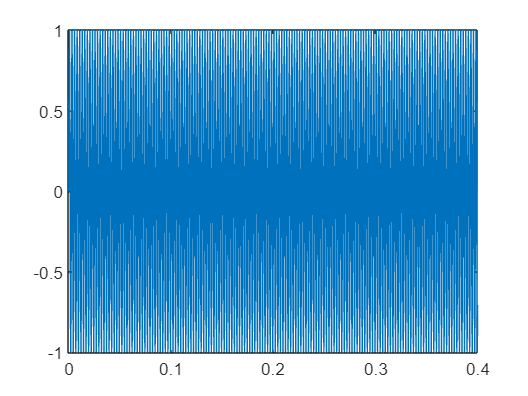

            
plot(t,X(121,:)) 

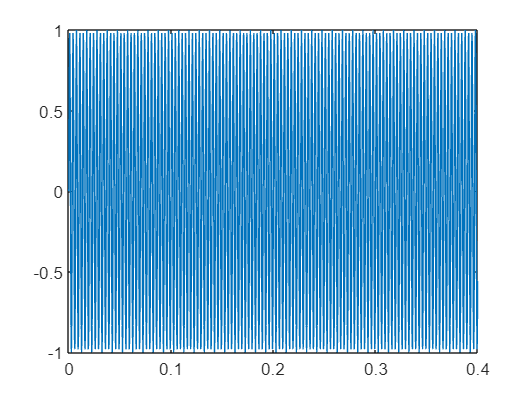

plot(t,X(1,:))

plot(t,X(30,:))

%X(167,:) = (1+a*(u(t-0.12)-u(t-0.22))).*x
%plot(t,x1)


